# Actividad 6 (Modelo_Dinamico_pendulo_1GDL)

### Robot Cartesiano (3GDL)

### A01737357

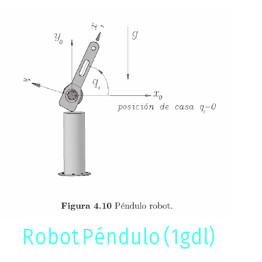

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t)   t    %Angulos de cada articulación
syms m1 Ixx1 Iyy1 Izz1  %Masas y matrices de Inercia
syms l1 lc1  %l=longitud de eslabones y lc=distancia al centro de masa
syms pi g a cero% de cada eslabón


 %Creamos el vector de coordenadas articulares
  Q= [th1];
  disp('Coordenadas generalizadas');pretty (Q);

Coordenadas generalizadas
th1(t)



 %Creamos el vector de velocidades articulares
  Qp= diff(Q, t);
  disp('Velocidades generalizadas');pretty (Qp);

Velocidades generalizadas
 d
-- th1(t)
dt



 %Creamos el vector de aceleraciones articulares
  Qpp= diff(Qp, t);
  disp('Aceleraciones generalizadas');pretty (Qpp);

Aceleraciones generalizadas
  2
 d
--- th1(t)
  2
dt




%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinematica directa

Se calcula las matrices de transformación homogenea utilizando en los parámetros de Denavit-Hartenberg.Permitiendo poder tener la posición y orientación del efecto final.Siendo fundamental para identificar el extremo del robot en base a los ángulos y desplazamientos de las articulaciones.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Se utilizan las matrices de transformación y el Jacobiano para calcular las velocidades lineales y angulares de cada eslabón en función de las velocidades articulares.Analizar cómo se mueve cada parte del robot y para controlar con precisión su trayectoria.



%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
    elseif RP(k)==1 
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');pretty (Jv_a);

Jacobiano lineal obtenido de forma analítica
/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
\        0        /



disp('Jacobiano ángular obtenido de forma analítica');pretty (Jw_a);

Jacobiano ángular obtenido de forma analítica
/ 0 \
|   |
| 0 |
|   |
\ 1 /




%Matriz de Jacobiano Completa
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
disp('Matriz de Jacobiano');pretty(Jacobiano);

Matriz de Jacobiano
/ -l1 sin(th1(t)) \
|                 |
|  l1 cos(th1(t)) |
|                 |
|        0        |
|                 |
|        0        |
|                 |
|        0        |
|                 |
\        1        /




%Obtenemos vectores de Velocidades Lineales y Angulares
V=simplify (Jv_a*Qp);
disp('Velocidad lineal obtenida mediante el Jacobiano lineal');pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/                  d        \
| -l1 sin(th1(t)) -- th1(t) |
|                 dt        |
|                           |
|                  d        |
|  l1 cos(th1(t)) -- th1(t) |
|                 dt        |
|                           |
\             0             /



W=simplify (Jw_a*Qp);
disp('Velocidad angular obtenida mediante el Jacobiano angular');pretty(W);

Velocidad angular obtenida mediante el Jacobiano angular
/     0     \
|           |
|     0     |
|           |
|  d        |
| -- th1(t) |
\ dt        /




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1)/2, l1, lc1); %La función subs sustituye l1 por lc1 en 
                                %la expresión P(:,:,1)/2

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];


%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos la velocidad angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

%Eslabón 1

%Ya lo calculamos previamente al multiplicar la matriz jacobiana por Qp

%Calculamos la energía cinética para cada uno de los eslabones

%Eslabón 1
V1_Total= V+cross(W,P01); %Se suma la velocidad lineal producida por la
                          % velocidad angular producida en el punto P01             
K1= (1/2*m1*(V1_Total))'*(V1_Total) + (1/2*W)'*(I1*W);

K1= simplify (K1);
disp('Energía Cinética en el Eslabón 1');pretty (K1);

Energía Cinética en el Eslabón 1
      |  d        | 2    |  d        | 2     ______           __          2             2
Izz1  | -- th1(t) |      | -- th1(t) |   cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
      | dt        |      | dt        |
--------------------- + -------------------------------------------------------------------------------
          2                                                 8 l1 lc1




K_Total= simplify (K1);
disp('Energía Cinética Total');pretty (K_Total);

Energía Cinética Total
      |  d        | 2    |  d        | 2     ______           __          2             2
Izz1  | -- th1(t) |      | -- th1(t) |   cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
      | dt        |      | dt        |
--------------------- + -------------------------------------------------------------------------------
          2                                                 8 l1 lc1



h1= P01(2);
U1=m1*g*h1;
U_Total= U1;
disp('Energía Potencial Total'); pretty(U_Total);

Energía Potencial Total
g lc1 m1 sin(th1(t))
--------------------
          2



%Obtenemos el Lagrangiano
Lagrangiano= simplify (K_Total - U_Total);
disp('Lagrangiano'); pretty (Lagrangiano);

Lagrangiano
      |  d        | 2                           |  d        | 2     ______           __          2             2
Izz1  | -- th1(t) |                             | -- th1(t) |   cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
      | dt        |     g lc1 m1 sin(th1(t))    | dt        |
--------------------- - -------------------- + -------------------------------------------------------------------------------
          2                       2                                                8 l1 lc1



%Modelo de Energía
H= simplify (K_Total+U_Total);
disp('Modelo de energía'); pretty (H)

Modelo de energía
      |  d        | 2                           |  d        | 2     ______           __          2             2
Izz1  | -- th1(t) |                             | -- th1(t) |   cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
      | dt        |     g lc1 m1 sin(th1(t))    | dt        |
--------------------- + -------------------- + -------------------------------------------------------------------------------
          2                       2                                                8 l1 lc1



toc

Elapsed time is 3.702888 seconds.
